num = 1;
den = [1 3 2]; % dois polos, -2 e -1
g = tf(num,den)

g =
 
        1
  -------------
  s^2 + 3 s + 2
 
Continuous-time transfer function.



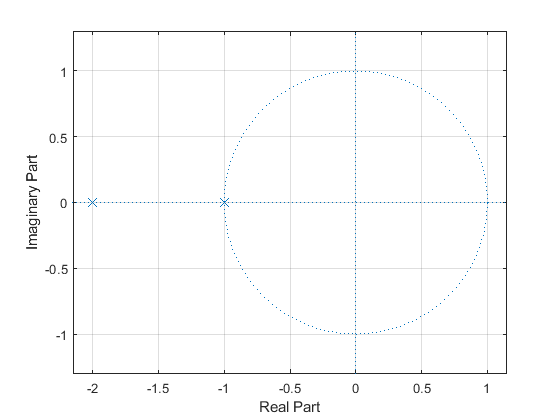

zplane(zero(g),pole(g));grid;

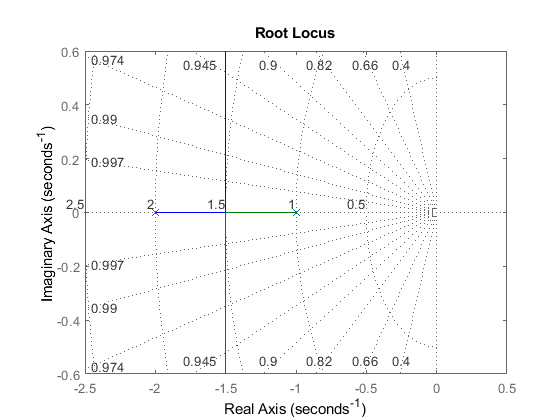

rlocus(g);grid

% Como temos dois polos sem pares, então temos duas assintotas
% O centroide das assintotas se dá por (-2 + -1)/2 = -1.5
% O Ângulo se dá por 180/#polos_sem_par = 90°

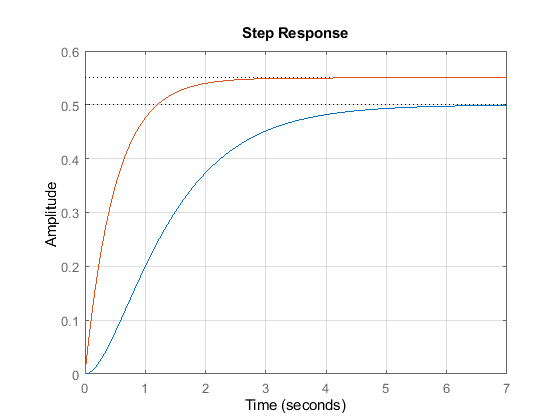

% Vendo o efeito da variação de um controle PD
% Nós vamos inserir um zero no controle ao fazer isso.
% pd = kp + kd*s; zero é -kp/kd (real)
kp =1.1;
kd =1.1;
pd = tf([kd kp],1);
% step(g) % para apenas g
stepplot(g,pd*g);grid; % resposta ao degrau unitário

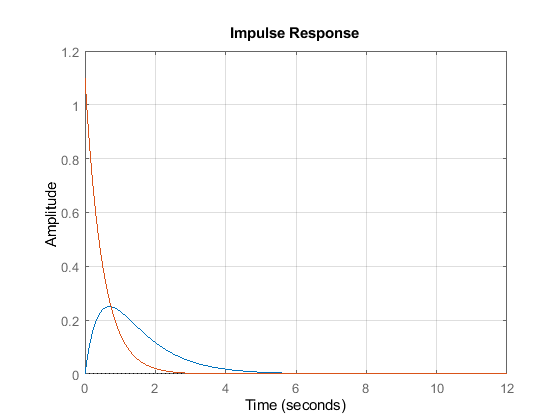

impulseplot(g,pd*g);grid; % resposta ao impulso unitário

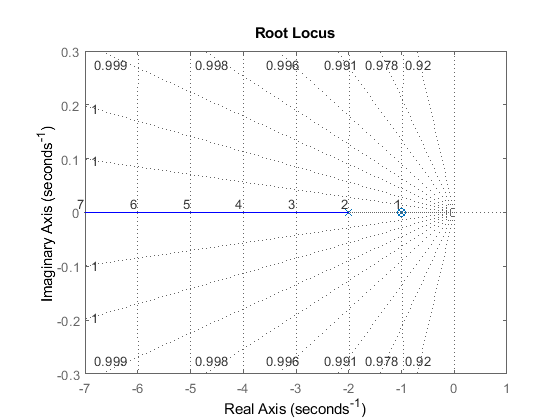

rlocus(pd*g);grid; % LGR da galera

Lembrando que a equação de erro em regime permantente (para o degrau unitário) se dá como:

$E_{\mathrm{SS}\left(\deg \left(u\right)\right)} =\frac{1}{1+{\mathrm{Ganho}}_{\mathrm{normalizado}} *K}$; Muitas vezes, o Ess é um parâmetro que temos que definir, ou que as regras falam qual é o seu valor. A partir daí, calcula-se o K necessário.

% vendo os casos para zeros em -0.5,  -1.5 e -2.5 e ver qual é o melhor dos
% três
% -0.5 (por algum motivo, não bate com o do slide do edin)
kp = 1; kd = 2;
pd = tf([kd kp],1)

pd =
 
  2 s + 1
 
Continuous-time transfer function.



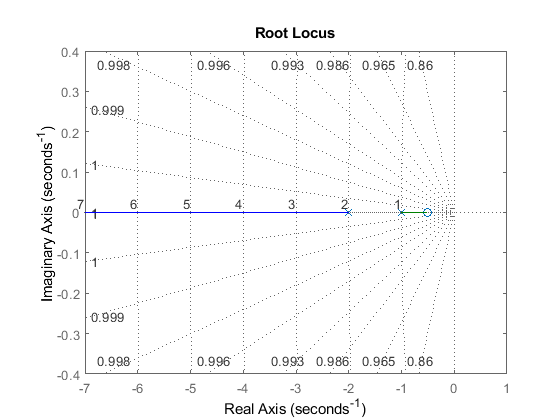

rlocus(pd*g);grid;

% vendo os casos para zeros em -0.5,  -1.5 e -2.5 e ver qual é o melhor dos
% três
% -1.5
kp = 3; kd = 2;
pd = tf([kd kp],1)

pd =
 
  2 s + 3
 
Continuous-time transfer function.



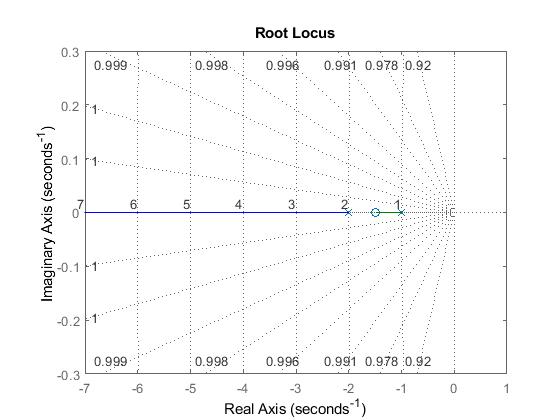

rlocus(pd*g);grid;

% vendo os casos para zeros em -0.5,  -1.5 e -2.5 e ver qual é o melhor dos
% três
% -2.5
kp = 5; kd = 2;
pd = tf([kd kp],1)

pd =
 
  2 s + 5
 
Continuous-time transfer function.



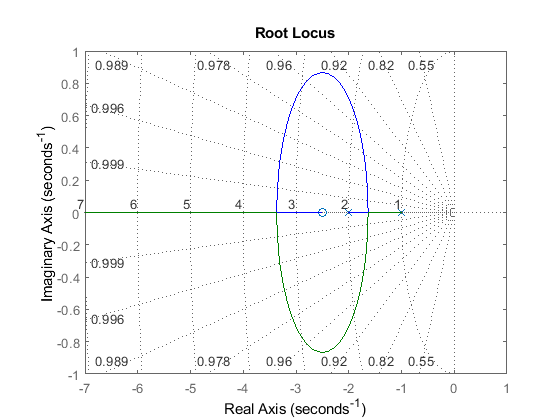

rlocus(pd*g);grid;